# Week 3: Rigid Motions Review

author

## Introduction

## Methods

## Results

### II-1

First, let's define our known variables.

R_1_2 = [ 1 0 0; 0 1/2 -sqrt(3)/2; 0 sqrt(3)/2 1/2; ]

R_1_2 =     1.0000         0         0
         0    0.5000   -0.8660
         0    0.8660    0.5000


R_1_3 = [ 0 0 -1; 0 1 0; 1 0 0; ]

R_1_3 =      0     0    -1
     0     1     0
     1     0     0


And, as we described above, we know that 

R_2_3 = transpose(R_1_2) * R_1_3

R_2_3 =          0         0   -1.0000
    0.8660    0.5000         0
    0.5000   -0.8660         0


Our resulting R_2_3 is 

And we can confirm the result:

R_1_2 * R_2_3

ans =          0         0   -1.0000
         0    1.0000         0
    1.0000         0         0


As we can see, the calculated R_2_3 is correct, as we can correctly derive R_1_3. ????

### II-2

sddsdf

H_0_1 = [ 1 0 0 0; 0 1 0 1; 0 0 1 1; 0 0 0 1; ];
H_0_2 = [ 1 0 0 -1/2; 0 1 0 3/2; 0 0 1 (1 + 10/100); 0 0 0 1; ];
H_0_3 = [ 0 1 0 -1/2; 1 0 0 3/2; 0 0 -1 3; 0 0 0 1; ];

adsfsdf

H_2_3 = inverse_transform(H_0_2) * H_0_3

H_2_3 =          0    1.0000         0         0
    1.0000         0         0         0
         0         0   -1.0000    1.9000
         0         0         0    1.0000


adsf

%

### II-3

Declare variables

syms phi theta psi
syms a1 a2 d1 d3 d4

rotation code

R_z_phi = [ cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1; ]

$$R\_z\_phi = \left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_x_180 = [ 1 0 0; 0 cosd(180) -sind(180); 0 sind(180) cosd(180); ]

R_x_180 =      1     0     0
     0    -1     0
     0     0    -1


R_0_1 = R_z_phi * R_x_180

$$R\_0\_1 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0\\ 0 & 0 & -1 \end{array}\right)$$

Transforms as defined:

H_0_1 = [ cos(phi) sin(phi) 0 cos(phi)*a1; sin(phi) -cos(phi) 0 sin(phi)*a1; 0 0 -1 d1; 0 0 0 1; ]

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & a_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_1_2 = [ cos(theta) -sin(theta) 0 cos(theta)*a2; sin(theta) cos(theta) 0 sin(theta)*a2; 0 0 1 0; 0 0 0 1; ]

$$H\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & a_{2}\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & a_{2}\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_2_3 = [1 0 0 0; 0 1 0 0; 0 0 1 d3; 0 0 0 1; ]

$$H\_2\_3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%H_3_4 = [ cos(psi) -sin(psi) 0 0; sin(psi) cos(psi) 0 0; 0 0 1 d4; 0 0 0 1; ]
H_3_4 = [ 1 0 0 0; 0 1 0 0; 0 0 1 d4; 0 0 0 1; ]

$$H\_3\_4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

asjadskjfds

H_0_4 = H_0_1 * H_1_2 * H_2_3 * H_3_4

$$H\_0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)+a_{2}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & a_{1}\,\sin\left(\varphi \right)-a_{2}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+a_{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}-d_{3}-d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}$$

Blah blah blah 

redefine vars

phi = 15;
theta = 30;
psi = 45;
a1 = 20; % Fixed distance part
a2 = 5;
d1 = 60; % Fixed distance part
% phi joint
phi_min = 1;
phi_max = 180;
% theta
theta_min = 45;
theta_max = 135;
% d3 joint
d3_min = 0.5;
d3_max = 15;
% d4 joint
d4_min = 0.5;
d4_max = 15;
%d4 = 15; % A prismatic joint - we'll say it can from

sadhfjf

H_0_1 = [ cosd(phi) sind(phi) 0 cosd(phi)*a1; sind(phi) -cosd(phi) 0 sind(phi)*a1; 0 0 -1 d1; 0 0 0 1; ];
H_1_2 = [ cosd(theta) -sind(theta) 0 cosd(theta)*a2; sind(theta) cosd(theta) 0 sind(theta)*a2; 0 0 1 0; 0 0 0 1; ];
H_2_3 = [1 0 0 0; 0 1 0 0; 0 0 1 d3; 0 0 0 1; ];
%H_3_4 = [ cosd(psi) -sind(psi) 0 0; sind(psi) cosd(psi) 0 0; 0 0 1 d4; 0 0 0 1; ]
H_3_4 = [ 1 0 0 0; 0 1 0 0; 0 0 1 d4; 0 0 0 1; ];

kdsflkdsfd

% phi = 15;
% theta = 30;
% psi = 45;
% a1 = 20; % Fixed distance part
% a2 = 5;
% d1 = 40; % Fixed distance part
% d3 = 8;
% d4 = 16;
% 
% clf
% figure
% axis([-100 100 -100 100 0 50])
% grid on
% hold on
% view([-40.5 16.8])
% 
% H_0_4 = H_0_1 * H_1_2 * H_2_3 * H_3_4;
% H_0_1 = [ cosd(phi) sind(phi) 0 cosd(phi)*a1; sind(phi) -cosd(phi) 0 sin(phi)*a1; 0 0 -1 d1; 0 0 0 1; ];
% H_1_2 = [ cosd(theta) -sind(theta) 0 cosd(theta)*a2; sind(theta) cosd(theta) 0 sind(theta)*a2; 0 0 1 0; 0 0 0 1; ];
% H_2_3 = [1 0 0 0; 0 1 0 0; 0 0 1 d3; 0 0 0 1; ];
% H_3_4 = [ 1 0 0 0; 0 1 0 0; 0 0 1 d4; 0 0 0 1; ];
% H_0_4 = H_0_1 * H_1_2 * H_2_3 * H_3_4;  
%     
% % Calculate our inverse transformations back to the 0 frame for all
% % coordinate frames
% H_1_0 = inv(H_0_1);
% H_2_0 = inv(H_1_2) * H_1_0;
% H_3_0 = inv(H_2_3) * H_2_0;
% %H_4_0 = inverse_transform(H_0_4);
% %H_4_0 = inverse_transform(H_3_4) * H_3_0
% H_4_0 = inv(H_0_4);
% 
% % Draw each coordinate axis
% origin = [0; 0; 0; 1;];
% axis_vector_length = 3;
% x = [ axis_vector_length; 0; 0; 1; ];
% y = [ 0; axis_vector_length; 0; 1; ];
% z = [ 0; 0; axis_vector_length; 1; ];
% 
% % x0y0z0
% draw_coordinate_axis(origin, z, y, z, 'red', 'green', 'blue');
% % x1y1z1
% origin_1 = H_1_0 * origin;
% draw_coordinate_axis(origin_1, H_1_0 * x, H_1_0 * y, H_1_0 * z, 'red', 'green', 'blue');
% % x2y2z3
% origin_2 = H_2_0 * origin;
% draw_coordinate_axis(origin_2, H_2_0 * x, H_2_0 * y, H_2_0 * z, 'red', 'green', 'blue');
% % x3y3z3
% origin_3 = H_3_0 * origin;
% draw_coordinate_axis(origin_3, H_3_0 * x, H_3_0 * y, H_3_0 * z, 'red', 'green', 'blue');
% % x4y4z4
% origin_4 = H_4_0 * origin;
% draw_coordinate_axis(origin_4, H_4_0 * x, H_4_0 * y, H_4_0 * z, 'red', 'green', 'blue');
% 
% % Draw the components of the robot next.
% % The first part is up d1, and then over a2 over
% line('XData', [origin(1) 0], 'YData', [origin(2) 0], 'ZData', [origin(3) d1], 'Color', 'black', 'LineWidth', 3);
% line('XData', [0 origin_1(1)], 'YData', [0 origin_1(2)], 'ZData', [d1 origin_1(3)], 'Color', 'black', 'LineWidth', 3);
% line('XData', [origin_1(1) origin_2(1)], 'YData', [origin_1(2) origin_2(2)], 'ZData', [origin_1(3) origin_2(3)], 'Color', 'black', 'LineWidth', 3);
% line('XData', [origin_2(1) origin_3(1)], 'YData', [origin_2(2) origin_3(2)], 'ZData', [origin_2(3) origin_3(3)], 'Color', 'black', 'LineWidth', 3);
% line('XData', [origin_3(1) origin_4(1)], 'YData', [origin_3(2) origin_4(2)], 'ZData', [origin_3(3) origin_4(3)], 'Color', 'black', 'LineWidth', 3);
% 
% hold off

#### animation

plot

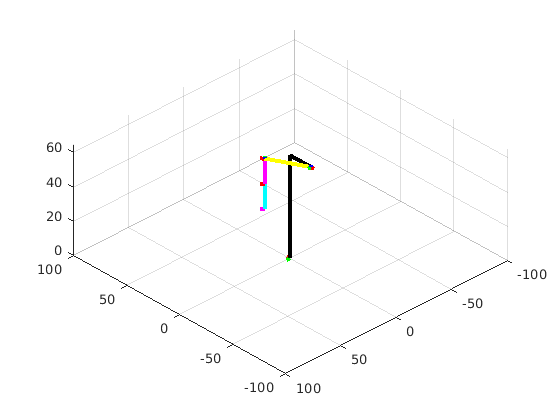

clf
figure
axis([-100 100 -100 100 0 65])
% axis equal
grid on
hold on
view([-133.8 55.7])

seconds_length = 10;
steps_per_second = 4;
steps = seconds_length * steps_per_second;
phi_delta = (phi_max - phi_min)/steps;
theta_delta = (theta_max - theta_min)/steps;
d3_delta = (d3_max - d3_min)/steps;
d4_delta = (d4_max - d4_min)/steps;

lines = [];
phi = phi_min;
theta = theta_min;
d3 = d3_min;
d4 = d4_min;

for step = 1:steps
    
    for index = 1:length(lines)
        delete(lines(index));
    end
    lines = [];
    
    H_w_0 = [ 1 0 0 0; 0 1 0 0; 0 0 deg2rad(-phi) 0; 0 0 0 1; ];
    H_0_1 = [ cosd(phi) sind(phi) 0 cosd(phi)*a1; sind(phi) -cosd(phi) 0 sind(phi)*a1; 0 0 -1 d1; 0 0 0 1; ];
    H_1_2 = [ cosd(theta) -sind(theta) 0 cosd(theta)*a2; sind(theta) cosd(theta) 0 sind(theta)*a2; 0 0 1 0; 0 0 0 1; ];
    H_2_3 = [1 0 0 0; 0 1 0 0; 0 0 1 d3; 0 0 0 1; ];
    H_3_4 = [ 1 0 0 0; 0 1 0 0; 0 0 1 d4; 0 0 0 1; ];
%     H_3_4 = [ cosd(psi) -sind(psi) 0 0; sind(psi) cosd(psi) 0 0; 0 0 1 d4; 0 0 0 1; ];
    H_0_4 = H_0_1 * H_1_2 * H_2_3 * H_3_4;  
        
    
    % Calculate our inverse transformations back to the 0 frame for all
    % coordinate frames
    H_0_w = inv(H_w_0);
    H_1_0 = inv(H_0_1) * H_0_w;
    H_2_0 = inv(H_1_2) * H_1_0;
    H_3_0 = inv(H_2_3) * H_2_0;
    %H_4_0 = inverse_transform(H_0_4);
    %H_4_0 = inverse_transform(H_3_4) * H_3_0
    H_4_0 = inv(H_0_4) * H_0_w;
    
    % Draw each coordinate axis
    origin = [0; 0; 0; 1;];
    axis_vector_length = 3;
    x = [ axis_vector_length; 0; 0; 1; ];
    y = [ 0; axis_vector_length; 0; 1; ];
    z = [ 0; 0; axis_vector_length; 1; ];
    
    % x0y0z0
    origin_0 = H_w_0 * origin;
    [x_line, y_line, z_line] = draw_coordinate_axis(origin_0, H_w_0 * x, H_w_0 * y, H_w_0 * z, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    % x1y1z1
    origin_1 = H_1_0 * origin;
    [x_line, y_line, z_line] = draw_coordinate_axis(origin_1, H_1_0 * x, H_1_0 * y, H_1_0 * z, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    % x2y2z3
    origin_2 = H_2_0 * origin;
    [x_line, y_line, z_line] = draw_coordinate_axis(origin_2, H_2_0 * x, H_2_0 * y, H_2_0 * z, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    % x3y3z3
    origin_3 = H_3_0 * origin;
    [x_line, y_line, z_line] = draw_coordinate_axis(origin_3, H_3_0 * x, H_3_0 * y, H_3_0 * z, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    % x4y4z4
    origin_4 = H_4_0 * origin;
    [x_line, y_line, z_line] = draw_coordinate_axis(origin_4, H_4_0 * x, H_4_0 * y, H_4_0 * z, 'magenta', 'yellow', 'cyan');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
%     Draw the components of the robot next.
%     The first part is up d1, and then over a2 over
    lines(end+1) = line('XData', [origin(1) 0], 'YData', [origin(2) 0], 'ZData', [origin(3) d1], 'Color', 'black', 'LineWidth', 3);
    lines(end+1) = line('XData', [0 origin_1(1)], 'YData', [0 origin_1(2)], 'ZData', [d1 origin_1(3)], 'Color', 'black', 'LineWidth', 3);
    lines(end+1) = line('XData', [origin_1(1) origin_2(1)], 'YData', [origin_1(2) origin_2(2)], 'ZData', [origin_1(3) origin_2(3)], 'Color', 'yellow', 'LineWidth', 3);
    lines(end+1) = line('XData', [origin_2(1) origin_3(1)], 'YData', [origin_2(2) origin_3(2)], 'ZData', [origin_2(3) origin_3(3)], 'Color', 'magenta', 'LineWidth', 3);
    lines(end+1) = line('XData', [origin_3(1) origin_4(1)], 'YData', [origin_3(2) origin_4(2)], 'ZData', [origin_3(3) origin_4(3)], 'Color', 'cyan', 'LineWidth', 3);
    
    % Increment all variables
    phi = phi + phi_delta;
    theta = theta + theta_delta;
    d3 = d3 + d3_delta;
    d4 = d4 + d4_delta;
    
    pause(seconds_length/steps)
    

end
    
hold off

Finally an animation

define the deltas, etc

% Run the animation

### Functions

adfdsaf

adfsafd

function [x_line, y_line, z_line] = draw_coordinate_axis(origin, x, y, z, x_color, y_color, z_color)    
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

sdfsdfdsfa

function out_transform = inverse_transform(in_transform)
   % First we get our rotation matrix and displacement from our homogenous
   % transform
   rotation = in_transform(1:3, 1:3);
   displacement = in_transform(1:3, 4);
   
   % The rotation inverse is merely the transpose
   rotation_inverse = transpose(rotation);
   % The displacement inverse is the negative transpose multiplied by the
   % displacement
   displacement_inverse = -rotation_inverse * displacement;
   out_transform = [ rotation_inverse(1) rotation_inverse(2) rotation_inverse(3) displacement_inverse(1); rotation_inverse(4) rotation_inverse(5) rotation_inverse(6) displacement_inverse(2); rotation_inverse(7) rotation_inverse(8) rotation_inverse(9) displacement_inverse(3); 0 0 0 1; ];

end

## Discussion